path = fullfile(pwd, "processed"); %File path

imds = imageDatastore(path,'IncludeSubfolders',true,'LabelSource',...
    'foldernames');

imds.ReadFcn = @preprocess;  % Apply function preprocess on all image on IMDS

numTrainFiles = 23  %Tune this depending on how many images you want to use for train for all category 

numTrainFiles = 23

[trainingSet,testSet] = splitEachLabel(imds,numTrainFiles);

Creating Bag-Of-Features.
-------------------------
* Image category 1: 1
* Image category 2: 10
* Image category 3: 100
* Image category 4: 101
* Image category 5: 102
* Image category 6: 103
* Image category 7: 104
* Image category 8: 105
* Image category 9: 106
* Image category 10: 107
* Image category 11: 108
* Image category 12: 109
* Image category 13: 11
* Image category 14: 110
* Image category 15: 111
* Image category 16: 112
* Image category 17: 113
* Image category 18: 114
* Image category 19: 115
* Image category 20: 116
* Image category 21: 117
* Image category 22: 118
* Image category 23: 119
* Image category 24: 12
* Image category 25: 120
* Image category 26: 121
* Image category 27: 122
* Image category 28: 123
* Image category 29: 124
* Image category 30: 125
* Image category 31: 126
* Image category 32: 127
* Image category 33: 128
* Image category 34: 129
* Image category 35: 13
* Image category 36: 130
* Image category 37: 131
* Image category 38: 132
* Image categ

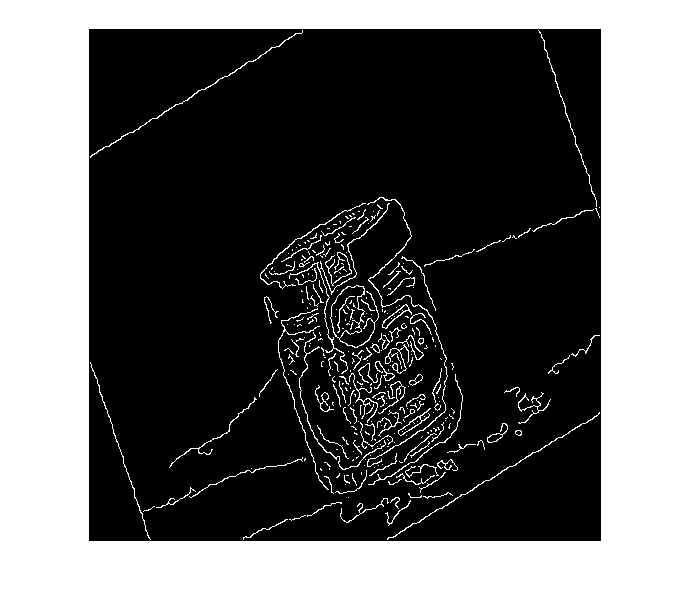

done. Extracted 5473127 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 81 has the least number of strongest features: 9734.
** Using the strongest 9734 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1946800
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 26/100 iterations (~6.10 seconds/iteration)...converged in 26 iterations.

* Finished creating Bag-Of-Features



func1 = @getSURFFeatures;
func2 = @getDCTFeatures;

bag = bagOfFeatures(trainingSet, "CustomExtractor", func1); % Place words into a bag of feature and process with custom function

%If no feature is found, it will return error. 
%Try lowering the MetricsThreshold in the function. If doesn't work, resize
%the image bigger.

Training an image category classifier for 200 categories.
--------------------------------------------------------
* Category 1: 1
* Category 2: 10
* Category 3: 100
* Category 4: 101
* Category 5: 102
* Category 6: 103
* Category 7: 104
* Category 8: 105
* Category 9: 106
* Category 10: 107
* Category 11: 108
* Category 12: 109
* Category 13: 11
* Category 14: 110
* Category 15: 111
* Category 16: 112
* Category 17: 113
* Category 18: 114
* Category 19: 115
* Category 20: 116
* Category 21: 117
* Category 22: 118
* Category 23: 119
* Category 24: 12
* Category 25: 120
* Category 26: 121
* Category 27: 122
* Category 28: 123
* Category 29: 124
* Category 30: 125
* Category 31: 126
* Category 32: 127
* Category 33: 128
* Category 34: 129
* Category 35: 13
* Category 36: 130
* Category 37: 131
* Category 38: 132
* Category 39: 133
* Category 40: 134
* Category 41: 135
* Category 42: 136
* Category 43: 137
* Category 44: 138
* Category 45: 139
* Category 46: 14
* Category 47: 140
* Catego

done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



classifier = trainImageCategoryClassifier(trainingSet, bag);  % Training Classifier

Evaluating image category classifier for 200 categories.
-------------------------------------------------------

* Category 1: 1
* Category 2: 10
* Category 3: 100
* Category 4: 101
* Category 5: 102
* Category 6: 103
* Category 7: 104
* Category 8: 105
* Category 9: 106
* Category 10: 107
* Category 11: 108
* Category 12: 109
* Category 13: 11
* Category 14: 110
* Category 15: 111
* Category 16: 112
* Category 17: 113
* Category 18: 114
* Category 19: 115
* Category 20: 116
* Category 21: 117
* Category 22: 118
* Category 23: 119
* Category 24: 12
* Category 25: 120
* Category 26: 121
* Category 27: 122
* Category 28: 123
* Category 29: 124
* Category 30: 125
* Category 31: 126
* Category 32: 127
* Category 33: 128
* Category 34: 129
* Category 35: 13
* Category 36: 130
* Category 37: 131
* Category 38: 132
* Category 39: 133
* Category 40: 134
* Category 41: 135
* Category 42: 136
* Category 43: 137
* Category 44: 138
* Category 45: 139
* Category 46: 14
* Category 47: 140
* Categor

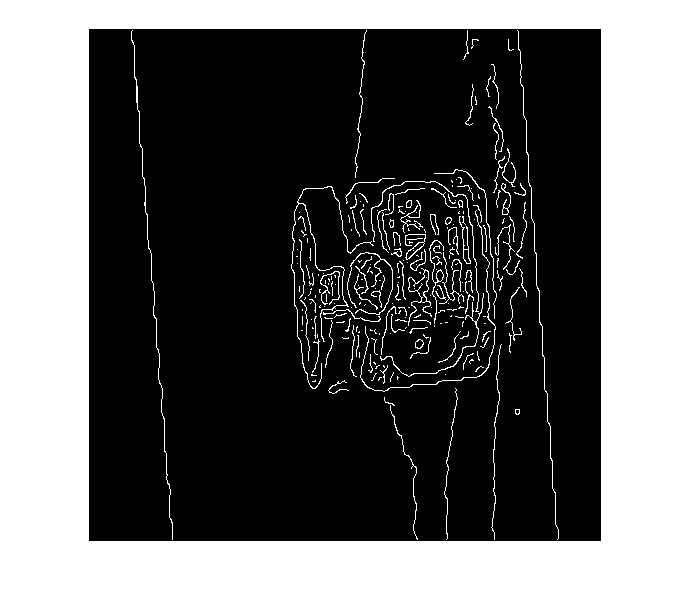

done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 PREDICTED
KNOWN   | 1      10     100    101    102    103    104    105    106    107    108    109    11     110    111    112    113    114    115    116    117    118    119    12     120    121 


confMatrix = evaluate(classifier,testSet);  % Testing how good our classifier is able to relate

mean(diag(confMatrix))   % Display results

ans = 0.2843

save classifier % Save the model

Solution from : [https://www.mathworks.com/matlabcentral/answers/496992-how-to-process-extracted-surf-features-for-svm-classifier](https://www.mathworks.com/matlabcentral/answers/496992-how-to-process-extracted-surf-features-for-svm-classifier)

## Preprocess function for image

function newI = preprocess(I)  % Preprocessing the image before passing to get extracted

    [height,width,numChannels] = size(I);
       
    I = imread(I);

    if numChannels > 1
        grayImage = rgb2gray(I);
    else
        grayImage = I;
    end

    grayImage = imresize(grayImage,[512 512]);
    
    %smoothing
    grayImage = medfilt2(grayImage);
    
    %contrast stretching
    grayImage = imadjust(grayImage,stretchlim(grayImage),[0.05 0.95]); % ~25% accuracy
    
    %sharpening
    %grayImage = unsharpFilter(grayImage);

    %Edge only
    grayImage = edge(grayImage, "canny");


    newI = grayImage;
end

function newI = unsharpFilter(I)
    mask = fspecial("gaussian",[5 5],1);
    blur = imfilter(I,mask);

    edge = imsubtract(I,blur);
    newI = imadd(I,edge);
end

## SURF feature extractor

function [features, metrics] = getSURFFeatures(I)
imshow(I);

[height,width,numChannels] = size(I);  % Get Aspects of the results
if numChannels > 1  % If more than 1 channel, convert to grayscale
    grayImage = rgb2gray(I);
else
    grayImage = I;
end

SURFPoint = detectSURFFeatures(grayImage,"MetricThreshold",1000);  % Detect feature using SURF, with feature of threshold of 1000 or above is accepted

features = extractFeatures(grayImage, SURFPoint,'Upright',true);  % Extract features from surfpoint

metrics = var(features,[],2);

end